addpath('Classes')


%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',false);
sympref('TypesetOutput',true);


# **Ball Plate Kinetics Revisited**

This script revisits the kinetics of the ball and plate system. Moments are taken about different locations than previous and the plate kinetics are considered with a friction and normal force acting rather than in the context of the compound system. The idea of bringing out the normal force explicitly as a form of actuation on the ball is considered here. For all the following analysis, the linear acceleration of the ball will be kept general, and in the frame of the plate for now. These must later be related to the state variables previously defined for the system in order to measure these global values. MAY ACTUALLY JUST START WITH THE GLOBAL ACCELERATION VECTOR IN TERMS OF THE STATE VARIABLES. Intermediate decoupling steps are taken to make the model effectively two decoupled teeter totters.

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics

end 

%Derive the Nonlinear Equations of motion in one go (may break this up into separate functions
%later, not sure yet)
BP_Kinetics.Derive_NL_EOMs;


## Kinetics of the Ball Alone

## 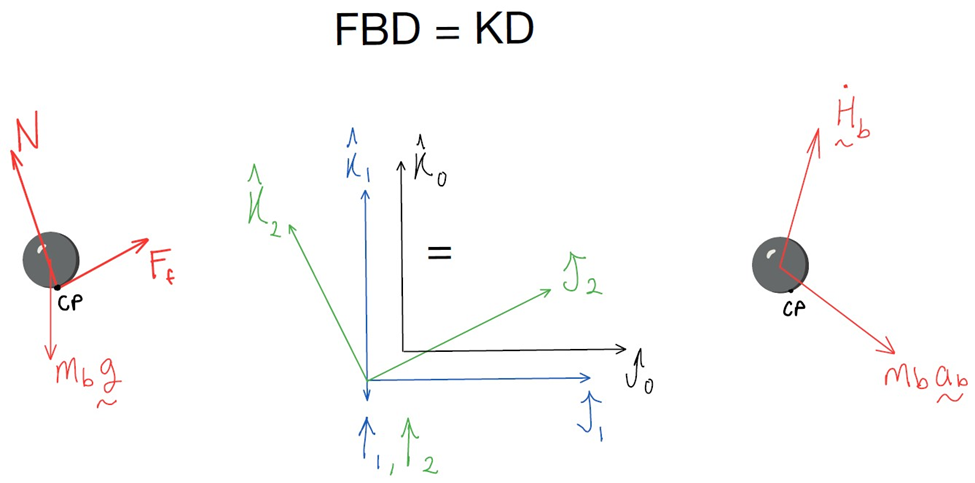

### Sum of Moments About Center of Mass of the Ball

The moment arm to the contact point here is the radius of the ball $r_b$ in the plate's negative z-direction as before


$$-arm_b^{(2)} = \left\lbrack \begin{array}{c}
0\\
0\\
-r_b 
\end{array}\right\rbrack$$


The sum of moments about the ball's center of gravity on the free body diagram is equal to the sum of the moments about the same point on the kinetic diagram. 


$$

\begin{array}{rl}

\sum{M_{cg~FBD} &=~~ \sum{M_{cg~KD}\\[6pt]

R^{20}(-arm^{(2)}_b \times F_f)

&=~~  

R^{20} \dot{H}^{(2)}_b

\end{array}$$


Resulting in a set of moment equations

SumMBall = expand(VDefs.R20*(cross(-VDefs.armb2s, VDefs.F_f))) == VDefs.R20*BP_Kinetics.Hb2ds;
SumMBall = subs(SumMBall, VDefs.symFunVec, VDefs.symVarVec)

Which can be decoupled from the $y$ and $\gamma$ states by assuming they are all zero. 

SumMBall = subs(SumMBall, [VDefs.gamma VDefs.gamma_dot VDefs.gamma_ddot VDefs.y VDefs.y_dot VDefs.y_ddot VDefs.psi_z VDefs.psi_dot_z VDefs.f_y],...
 [0 0 0 0 0 0 0 0 0])

$$SumMBall = \left[\begin{array}{c} 0=0\\ -f_{x}\,r_{b}=\frac{2\,m_{b}\,r_{b}\,\ddot{x}}{5}+\frac{2\,\ddot{\beta }\,m_{b}\,{r_{b}}^{2}}{5}\\ 0=0 \end{array}\right]$$

f_x = isolate( SumMBall(2),VDefs.f_x) %Substituted into the force equations below

$$f\_x = f_{x}=-\frac{2\,m_{b}\,\ddot{x}}{5}-\frac{2\,\ddot{\beta }\,m_{b}\,r_{b}}{5}$$

### Sum of Forces for the Ball


$$

\begin{array}{rl}

\sum{F_{FBD} &=~~ \sum{F_{KD}\\[6pt]

R^{20}(F_f + N)

&=~~  

R^{20}m_b a^{(2)}_b

\end{array}$$


SumFBall = VDefs.R20*(VDefs.F_f + VDefs.N) == VDefs.R20*VDefs.m_b*VDefs.r2s